clear
clc
h=0.53;

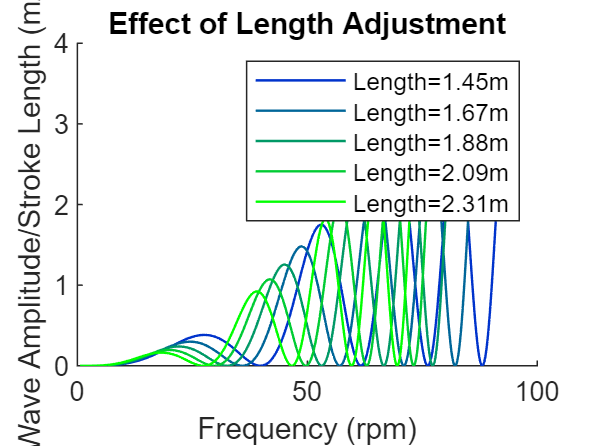

n_inc=5;

L_max=2.31;
%L_min=L_max/2;
%L=linspace(L_min,L_max,n_inc);
%L_min=L_max/2+0.3;
%L_max_brace=L_max-0.3;
L_min=1.45;
L=linspace(L_min,L_max,n_inc);

n=0.02:0.02:5;
leg=cell(n_inc,1);%legend entries

figure
hold on
for i=1:n_inc
    [w,H_res]=TF_res(n,L(i),h);
    H_amp=TF_tank(w,h);
    H_t=H_res.*H_amp;
    rpm=w*60/(2*pi);
    c=[0 0 1]+i/n_inc*[0 1 -1];
    plot(rpm,H_t,'Color',c,'LineWidth',0.8)
    leg{i}=['Length=',num2str(L(i),'%.2f'),'m'];
end
hold off
xlabel('Frequency (rpm)')
ylabel('Wave Amplitude/Stroke Length (m/m)')
title('Effect of Length Adjustment')
legend(leg)